**Convex sets. Ball**

Find the unit ball B(0, 1) w.r.t. ${\left\|\ldotp \right\|}_1$, ${\left\|\ldotp \right\|}_2$, ${\left\|\ldotp \right\|}_{\infty }$, ${\left\|\ldotp \right\|}_A$ where  $\left\lbrack \begin{array}{cc}
2 & 0\\
0 & 1
\end{array}\right\rbrack$

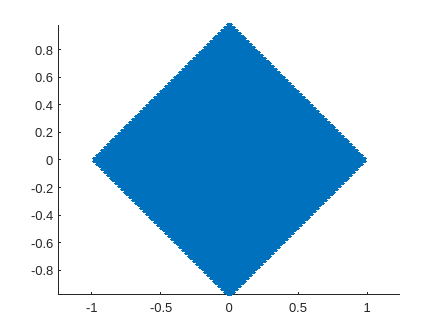

% Norm L1
r = 1;
c = 0;
n = 100; % number of points to plot
[x,y] = meshgrid(linspace(-r,r,n));
z = abs(x) + abs(y);
mask = z <= r;  % only plot points inside the unit ball



figure();
scatter(x(mask), y(mask), 10, 'filled');
axis equal;

% Norm L2 

z = sqrt((abs(x) + abs(y)).^2);
mask = z <= r;  % only plot points inside the unit ball

figure();
scatter(x(mask), y(mask), 10, 'filled');
axis equal;

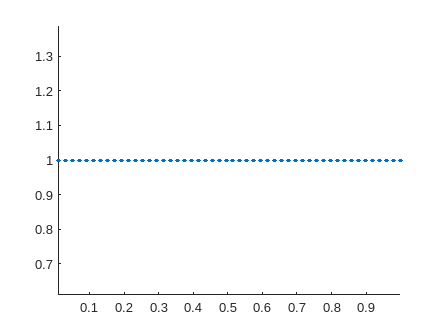

% Norm Infinity 

x = max(abs(x));
y = max(abs(y));
%mask = z <= r;  % only plot points inside the unit ball

figure();
scatter(x, y, 10, 'filled');
axis equal;